# Filter Responses of Antialiasing Filter

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code generates a signal with one tone at 1900 Hz.

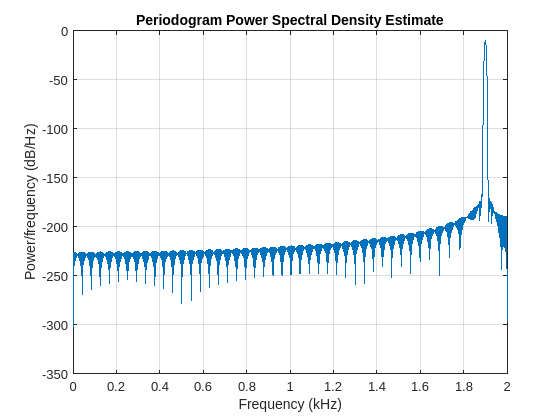

fs = 4000;
t = 0:1/fs:0.5;
sig = sin(2*pi*1900*t);
periodogram(sig,kaiser(numel(sig),19),2^12,fs)

This code interpolates the signal and plots the new power spectrum.

sigup = resample(sig,6,1)

sigup =     0.0000    0.1289    0.2524    0.3375    0.3563    0.2944    0.1565   -0.0332   -0.2333   -0.3955   -0.4763   -0.4483   -0.3092   -0.0841    0.1773    0.4122    0.5602    0.5785    0.4543    0.2096   -0.1006   -0.4015   -0.6166   -0.6872   -0.5882   -0.3362    0.0113    0.3701    0.6492    0.7743    0.7076    0.4585    0.0846   -0.3227   -0.6602   -0.8394   -0.8095   -0.5721   -0.1825    0.2630    0.6515    0.8819    0.8916    0.6731    0.2785   -0.1942   -0.6246   -0.9016   -0.9517   -0.7586


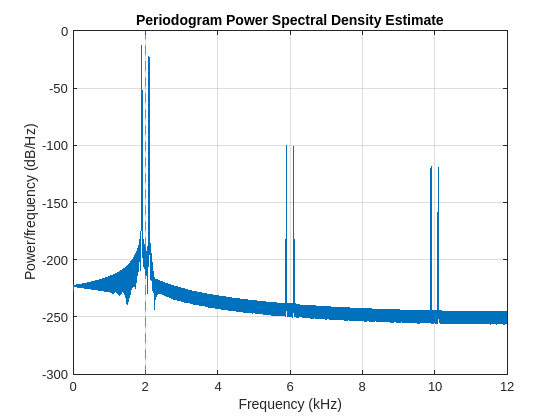

fsup = fs*6;
w = kaiser(numel(sigup),19);
periodogram(sigup,w,[],fsup)
xline(fs/2/1000,"m--")

## Task 1

Why does the antialiasing filter only decrease the power of the first image by 11 dB? To find out, you can look at the magnitude response of the filter.

You can get the coefficients of the antialising filter used by `resample` to look at the filter characteristics. To get the coefficient vector, use a second output with the `resample` function:

`[``y``,``b``]` `=` `resample``(``x``,``p``,``q``)`

[sigup,b] = resample(sig,6,1)

sigup =     0.0000    0.1289    0.2524    0.3375    0.3563    0.2944    0.1565   -0.0332   -0.2333   -0.3955   -0.4763   -0.4483   -0.3092   -0.0841    0.1773    0.4122    0.5602    0.5785    0.4543    0.2096   -0.1006   -0.4015   -0.6166   -0.6872   -0.5882   -0.3362    0.0113    0.3701    0.6492    0.7743    0.7076    0.4585    0.0846   -0.3227   -0.6602   -0.8394   -0.8095   -0.5721   -0.1825    0.2630    0.6515    0.8819    0.8916    0.6731    0.2785   -0.1942   -0.6246   -0.9016   -0.9517   -0.7586


b =    -0.0000   -0.0007   -0.0015   -0.0021   -0.0022   -0.0015    0.0000    0.0019    0.0038    0.0050    0.0049    0.0032   -0.0000   -0.0040   -0.0077   -0.0098   -0.0094   -0.0060    0.0000    0.0072    0.0136    0.0171    0.0161    0.0101   -0.0000   -0.0119   -0.0224   -0.0280   -0.0262   -0.0163    0.0000    0.0190    0.0354    0.0441    0.0411    0.0255   -0.0000   -0.0296   -0.0552   -0.0687   -0.0642   -0.0400    0.0000    0.0468    0.0880    0.1106    0.1045    0.0661   -0.0000   -0.0805


## Task 2

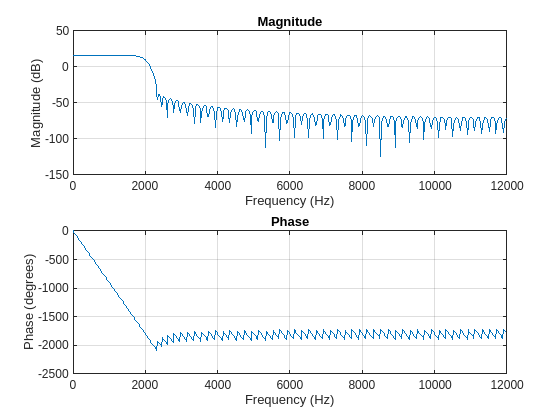

freqz(b,1,[],fsup)

## Task 3

The first imaged tone is located at 2100 Hz. The magnitude response plot shows that the power at 2100 Hz is not filtered out much. Generally, this filter removes frequency content above about 2000 Hz, but because the image is located near 2000 Hz, you need a steeper filter to remove the image. To improve the approximation of the filter, you can increase its order.

First, you can figure out the order of the default filter. The filter order is one less than the length of the filter:

`numel``(``b``)``-1`

Or you can use the `filtord` function, which returns the filter order:

`filtord``(``b``)`

ord = filtord(b)

ord = 120

## Task 4

To increase the order, you can add another input to the `resample` function.

`[``y``,``b``]` `=` `resample``(``x``,``p``,``q``,``n``)`

`resample` uses an antialiasing filter of order 2× `n` × `max``(``p``,``q``)`.

The default value for `n` is 10, so that's why the order is 120 (2×10×6)

A larger filter order enables you to get a steeper transition region. You'll learn more about the relationship between filter order and other filter specifications in the next module.

[sigup2,b2] = resample(sig,6,1,30)

sigup2 =     0.0000    0.2479    0.4591    0.5767    0.5637    0.4143    0.1565   -0.1523   -0.4391   -0.6325   -0.6808   -0.5658   -0.3091    0.0317    0.3761    0.6398    0.7554    0.6900    0.4541    0.1011   -0.2855   -0.6117   -0.7955   -0.7885   -0.5879   -0.2391    0.1754    0.5547    0.8047    0.8614    0.7073    0.3769   -0.0514   -0.4735   -0.7853   -0.9082   -0.8092   -0.5099   -0.0814    0.3723    0.7395    0.9287    0.8912    0.6341    0.2183   -0.2550   -0.6697   -0.9231   -0.9513   -0.7456


b2 =    -0.0000   -0.0002   -0.0004   -0.0005   -0.0004   -0.0003   -0.0000    0.0003    0.0006    0.0007    0.0006    0.0004   -0.0000   -0.0004   -0.0008   -0.0010   -0.0009   -0.0005    0.0000    0.0006    0.0011    0.0013    0.0012    0.0007    0.0000   -0.0008   -0.0014   -0.0017   -0.0015   -0.0009   -0.0000    0.0010    0.0018    0.0021    0.0019    0.0011   -0.0000   -0.0012   -0.0022   -0.0027   -0.0024   -0.0014    0.0000    0.0015    0.0027    0.0033    0.0029    0.0017   -0.0000   -0.0019


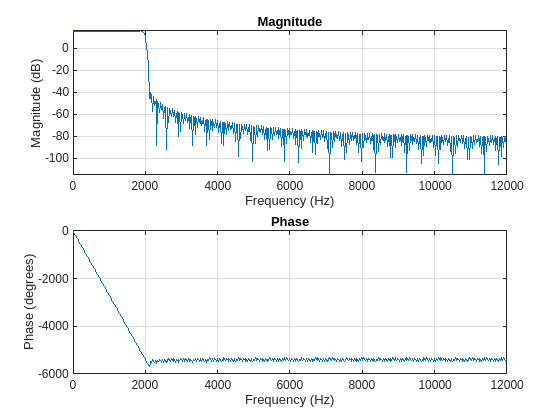

freqz(b2,1,[],fsup)

## Task 5

Locate 2100 Hz on the new magnitude response plot. How do you think the spectrum of `sigup2` will look compared to `sigup`?

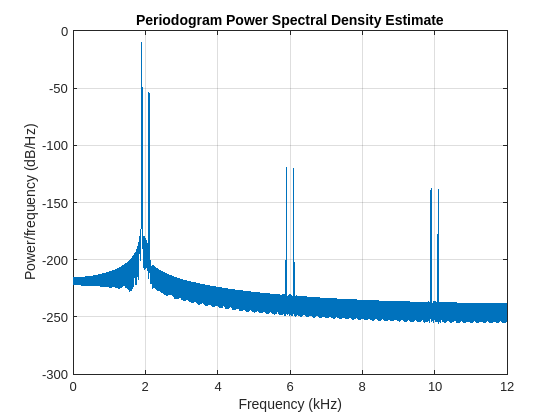

periodogram(sigup2,w,[],fsup)

## Task 6

The image at 2100 Hz now has a lower magnitude, but a downside to using the longer filter is that there will also be a longer delay.

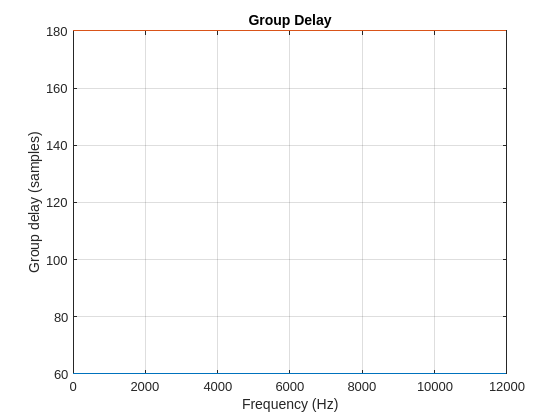

grpdelay(b,1,[],fsup)
hold on
grpdelay(b2,1,[],fsup)
hold off